# Fourier Analysis of Signals Using DFT 

Let $x[n] =  A_0\cos(w_0n) +  A_1\cos(w_1n), n \in \mathbb{Z}$ be the discrete-time signal obtained by sampling $x(t)$with sampling frequency $T_s$. 

Write down expressions for $x(t)$: A0cos(pi*t/3*Ts) +A1cos(2*pi*t/3*Ts)

Let us assume that we have $x[n]$values available for $0\leq n\leq L-1$only using which we are required to do frequency analysis. We assume that $x[n]=0$ for $n\notin \{0,L-1\}$.  That is, we have the windowed sequence, $v[n]$, defined as follows:$v[n] = x[n]w[n]$, where $w[n] = 1$for $0\leq n\leq L-1$ and $w[n] =0$, otherwise. This window is called as the rectangular window. 

#### Coding Question 

Write a code to get $x[n], w[n] $and $v[n]$

clc;
clear all;
w0 = 2*pi/6;
w1 = 2*pi/3;
A1 = 1;
A2 = 1;
L=64

L = 64

n = 0:L-1

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x =   A1*cos(w0*n)+A2*cos(w1*n);
rectWindow = ones(1,L)

rectWindow =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


v = rectWindow.*x

v =     2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000   -1.0000         0   -1.0000   -0.0000    2.0000    0.0000


#### Coding Question 

Compute $N$-point DFT, $V[k]$ of $v[n]$ and plot $V[k]$ from $k\in [0, N-1]$

n=0:1:L-1;
size(n)

ans =      1    64


x =    A1*cos(w0*n)+A2*cos(w1*n);             % EXERCISE: Construct x[n] defined above  
size(x)

ans =      1    64


rectWindow1 = n>=0;
rectWindow2=n<=L;
finalrectWindow=(1/2)*(rectWindow1+rectWindow2);
size(finalrectWindow)% EXERCISE Define a rectangular window of length L, w[n]

ans =      1    64



v =  x.'*finalrectWindow; % EXERCISE: Compute the windowed sequence, v[n]
size(v)

ans =     64    64


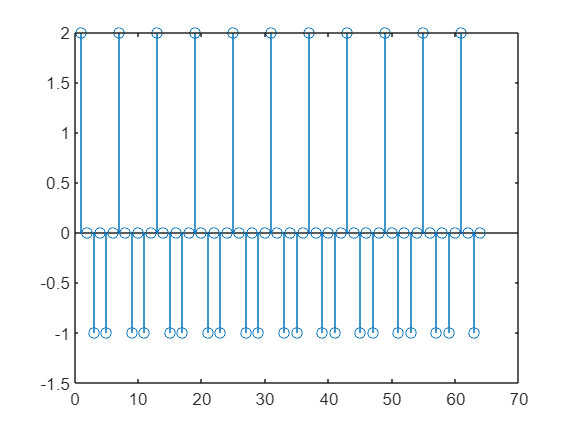


stem(v);


N = 64; % EXERCISE: Define a suitable N
 
V = fft(v,N); % EXERCISE: Compute N-point DFT
%K=1:N-1;

subplot(2,1,1);
stem(abs(V)); %  EXERCISE: Plot Magnitude of V
xlabel('Samples')
ylabel('|V[k]|')
title('Magnitude of V[k]')

subplot(2,1,2); 
stem(angle(V)); %  EXERCISE: Plot Phase of V
xlabel('Samples')
ylabel('ARG{V[k]}')
title('Phase of V[k]')

It is bit difficult to read the above plots as we do not readily see which samples correspond to which discrete-time frequency. Hence, let us try to view the DTFT of v[n] (approximate). Let us first compute the DTFT of $w[n]$.

#### Coding Question 

Compute the DTFT of w[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

N = 64; % EXERCISE: Define a suitable N

omega = 1:64; % EXERCISE: Compute sample points of discrete-time frequency
            
W = fft(rectWindow) % EXERCISE: Compute N-point DFT

W =     64     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


subplot(2,1,1);
plot(abs(W)); %  EXERCISE: Plot Magnitude  of W
xlabel('\omega')
ylabel('|W(e^{j\omega})|')
title('Magnitude Response of w[n]')
p = linspace(-pi,pi,64)

p =    -3.1416   -3.0419   -2.9421   -2.8424   -2.7427   -2.6429   -2.5432   -2.4435   -2.3437   -2.2440   -2.1443   -2.0445   -1.9448   -1.8451   -1.7453   -1.6456   -1.5459   -1.4461   -1.3464   -1.2467   -1.1469   -1.0472   -0.9475   -0.8477   -0.7480   -0.6483   -0.5485   -0.4488   -0.3491   -0.2493   -0.1496   -0.0499    0.0499    0.1496    0.2493    0.3491    0.4488    0.5485    0.6483    0.7480    0.8477    0.9475    1.0472    1.1469    1.2467    1.3464    1.4461    1.5459    1.6456    1.7453


subplot(2,1,2); 
plot(p,angle(W)); %  EXERCISE: Plot Magnitude  of W
xlabel('\omega')
ylabel('ARG{W(e^{j\omega})}')
title('Phase Response of w[n]')


#### Coding Question 

Compute the DTFT of v[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

N = 64; % EXERCISE: Define a suitable N

omega =1:64 % EXERCISE: Compute sample points of discrete-time frequency

omega =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


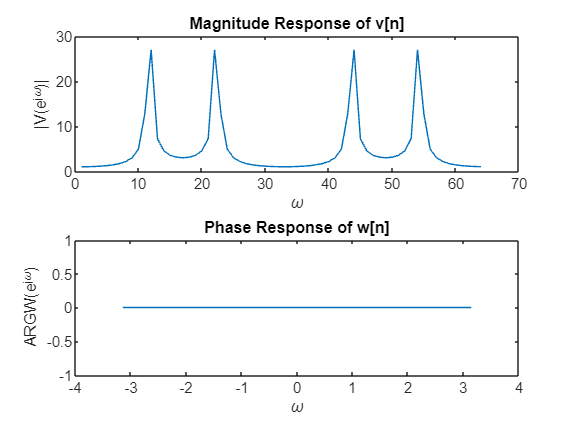

V = fft(v); % EXERCISE: Compute N-point DFT


subplot(2,1,1);
plot(abs(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\omega')
ylabel('|V(e^{j\omega})|')
title('Magnitude Response of v[n]')

p = linspce(-pi,pi,64)

Unrecognized function or variable 'linspce'.

subplot(2,1,2); 
plot(p, V); %  EXERCISE: Plot Magnitude  of V
yine(0)
xlabel('\omega')
ylabel('ARG{V(e^{j\omega})}')
title('Phase Response of v[n]')


#### Coding Question 

Now, suppose the $x(t)$ was sampled at sampling period of $T_s$, then plot $X(j\Omega)$, your estimate of the continuous-time Fourier transform of $x(t)$. 

t = linspace(-3,3,1000)
Ts = 3.333*10^(-3) ; % EXERCISE: Choose a sensible sampling frequency
x_t = A1*cos(100*pi*t)+A2*cos(200*pi*t)
X_jOmega = fft(x_t); %EXERCISE:  Compute the continuous-time Fourier transform

subplot(2,1,1);
plot(t,abs(X_jOmega)); %  EXERCISE: Plot Magnitude  of V
xlabel('\Omega')
ylabel('|X(j\Omega})|')
title('An Estimate of the Magnitude Response of x(t)')

subplot(2,1,2); 
plot(t, angle(V)); %  EXERCISE: Plot Magnitude  of V
xlabel('\Omega')
ylabel('ARG{X(j\Omega)}')
title('An Estimate of the Phase Response of x(t)')


#### Inference Question 

Now, repeat the above four questions for 

- 
$$w_0 = 2\pi/14, w_1 = 2\pi/15$$


- 
$$w_0 = 2\pi/14, w_1 = 2\pi/12$$


- 
$$w_0 = 2\pi/14, w_1 = 4\pi/25$$


- What do you observe on the number of peaks?  

- How does your observation change if you change $L$? 

- How does your observation change if you change $N$? 

- Do the amplitudes of $|V[k]|$reflect that of $|V(e^{j\omega})|$? Why? 

- Do the amplitudes of $|V(e^{j\omega})|$ reflect that of $|X(e^{j\omega})|$?  Why? 

## Short-Time Fourier Transform

Previously we assumed that the frequencies and amplitudes of the sinusoids do not change with time. However, in practice, usually amplitudes and frequencies of a signal change with time. For analyzing the frequency content of that we consider only a small window and analyse its frequency content, and slide the window to look at the frequency content of the next window and so on. This is called the Short-Time Fourier Transform. 

Read the first page of Section 10.3 of "Discrete-Time Signal Processing", 2nd Edition by Alan V. Oppenheim, Ronald Schafer and John R. Buck. 

- How is the short-time Fourier transform defined as, for a sequence $x[n]$.

        ANSWER:  The data to be transformed could be broken up into chunks or frames and each chunk is fourier transformed, which records magnitude and phase for each point in time and frequency.

- Now, construct the following frequency modulated chirp signal: $x[n] = \cos(\omega_0 n^2), $ where $\omega_0 = 2\pi\times 7.5\times10^{-6}. $

% ENTER YOUR CODE HERE
n = -300:300
x_chirp = chirp(n.*n,7.5*10^-6)   % chirp normally sweeps frequency of cosine of "t"

- Now compute the short-term Fourier transform of $x[n], $ with rectangular window, $w[n]$  of some L  length. 

L  = 256 % LENGTH OF THE RECTANGULAR WINDOW
w = rectwin(L); % RECTANGULAR WINDOW
X_stft = stft(x_chirp,Window = w); % COMPUTE STFT of x[n] using rectnagluar window w[n].
             % DISPLAY THE IMAGE IN A TWO DIMENSIONAL PLOT.    
y_reshape = reshape(stft(X_stft,Window=w),[256*6,1]);
plot(abs(y_reshape))         

- Now use [spectrogram](https://in.mathworks.com/help/signal/ref/spectrogram.html) to compute the short-time Fourier transform of the above $x[n]$ and compare it with what you had got. 

%WRITE YOUR CODE HERE
L  = 256 % LENGTH OF THE RECTANGULAR WINDOW
w = rectwin(L); % RECTANGULAR WINDOW
%X_stft = stft(y,Window = w);
d = seconds(1);
stft(x_chirp,d,Window=w,OverlapLength=98,FFTLength=256); 

# Practical Experiment

- Now count 1 to 5 in any language of your interest (try your mother tongue) and record it.

% COUNT 1-5 AND RECORD IT.
[y,Fs] = audioread("one-five.wav")
sound(y,Fs)
plot(y)

- Now compute the spectrogram of the signal you have recorded

% COMPUTE THE SPECTROGRAM


- Play with different parameters of the spectrogram and write your 3 observations: 

        ANSWER: 

- Now compute the [periodogram](https://in.mathworks.com/help/signal/ref/periodogram.html) of the recorded signal:

%WRITE YOUR CODE HERE

- What information does the periodogram give? 

        ANSWER: 

- Until what frequency does human voice contain significant power density? 

        ANSWER: 

# Design and Comparison of FIR and IIR Filters 

Design and compare FIR and IIR filters. Refer to the below diagram for the lab.  

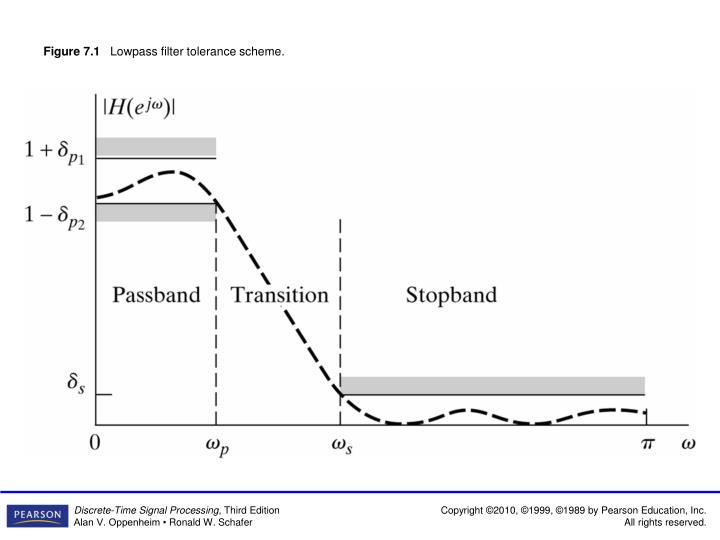

## FIR Filter Design 

Now, we will design FIR filters satisfying the following specifications: 

- 
$$\omega_p =0.4\pi
$$


- 
$$\omega_s = 0.6\pi
$$
 

- 
$$\delta_{p_1}=\delta_{p_2}=0.01, \;\;\delta_s=0.01$$


### Windowing Method

Now, using the Kaiser window, design  window-based FIR filter with the above specifications 

- What is the filter order (approx)?  $\textrm{ENTER}\;\textrm{YOUR}\;\textrm{ANSWER}\;\textrm{HERE}$

- Open "filterDesigner" tool (you can open it by typing *filterDesigner* in the Matlab command window as shown below.)

                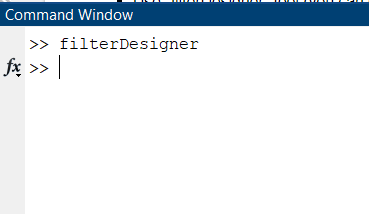

       Open the below view. Here you can specify frequency and magnitude specifications. 

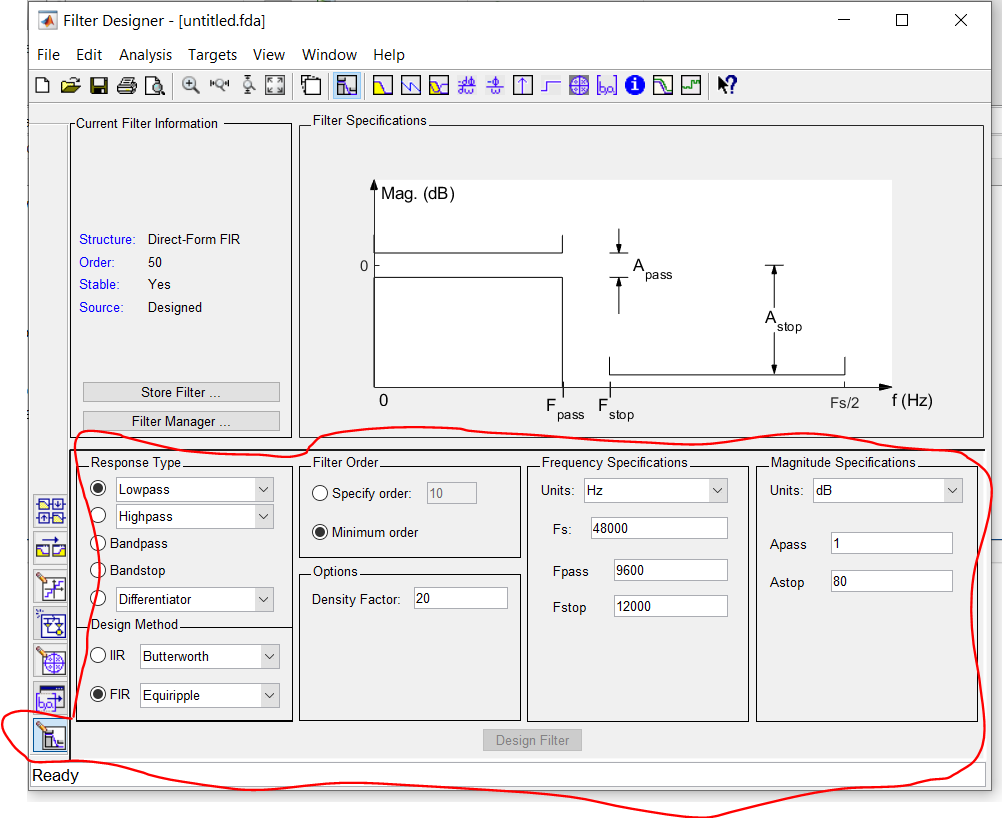

-   Obtain the coefficients of the filter. Write down the coefficients below. 

% ASSIGN THE FILTER COEFFICIENTS TO "b". 
b = [];

- Does the number of entries in $b$ correspond to the above theoretically obtained (by you) filter order ?

           * ANSWER*

- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.  

           * ANSWER*

### Min-Max Method : 

You already know that the the FIR filter designed using the windowing method has minimimum mean squared error with respect to the ideal filter response. Now, we will design a filter which minimizes the maximum error with respect to the ideal filter. Design an FIR filter satisfying the specifications using  [firpm](https://in.mathworks.com/help/signal/ref/firpm.html).

% WRITE YOUR CODE HERE





- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.      

           * ANSWER*

- Give a comparison with the filter obtained using the windowing method above.  

           * ANSWER*

## IIR Filter Design

In this part, we will solve Example 5 of Chapter 7 of Oppenheim and Schafer textbook using the *filterDesigner* tool. Although you need to know how impulse invariance and bilinear transform methods work, you almost never design discrete-time filters manually. Almost always, you will use some tools, such as *filterDesigner* MATLAB. 

**Note:**  From this course point of view, you should know how to manually design filters using impulse invariance and bilinear transform for IIR filters, and window and equiripple (also called as minimax or Parks-McClellan methods) for FIR filters. 

**References:** 

- Example 5 of Chapter 7 of Oppenheim and Shafer textbook, 3rd Edition (If you have the 2nd Edition, see Example 7.4, 7.5 and 7.6 for the IIR part starting from Page 458, and Section 7.5.1 on Page 503 for FIR part )

- [https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf](https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf)

Design the following filter: $\delta_{p_1} = \delta_{p_2} = 0.01, \;\;
\delta_s = 0.001, \;\; \omega_p = 0.4\pi, \;\; \omega_s = 0.6\pi
$using

- IIR Butterworth

- IIR Chebyshev Type 1

- IIR Chebyshev Type 2

- FIR Window - Kaiser

and answer the following for each of the above methods: 

- Order of the filter

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

An example is shown below for IIR Butterworth filter: 

### IIR Butterworth filter

Open the Filter Designer tool, by typing *filterDesigner *in the command window as shown below. 

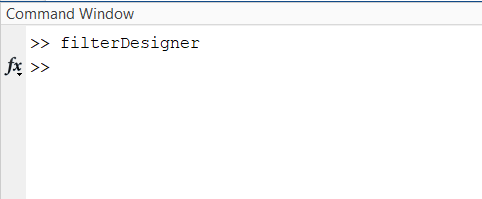

We first note that in the Filter Designer tool, for designing IIR filter,  it is assumed that $\delta_{p_1}=0
$ (red annotations in Fig. 1). Hence, in order to design the filter using this tool,  we first scale all the tolerance parameters, design the filter using the toolbox and then rescale them back.

- **Scaling the parameters:** Let $\delta_{p_1}',\; \delta_{p_2}'$and $\delta_s'$ be the new parameters.  We want to scale all the parameters according to the requirement that $\delta_{p_1}'=0$.  This implies, $1-\delta_{p_2}' = (1-\delta_{p_2})/(1+\delta_{p_1}) = (1-0.01)/1.01=  0.9802$. Hence, $\delta_{p_2}' = 1-0.9802=0.0198$. Similarly, $\delta_s' = \delta_s/(1+\delta_{p_1}) = 0.001/1.01 = 0.00099$. 

- **Filter Design:** Now, we feed these values in the Filter Designer tool  and design the filter (blue annotations in Fig. 1)

. 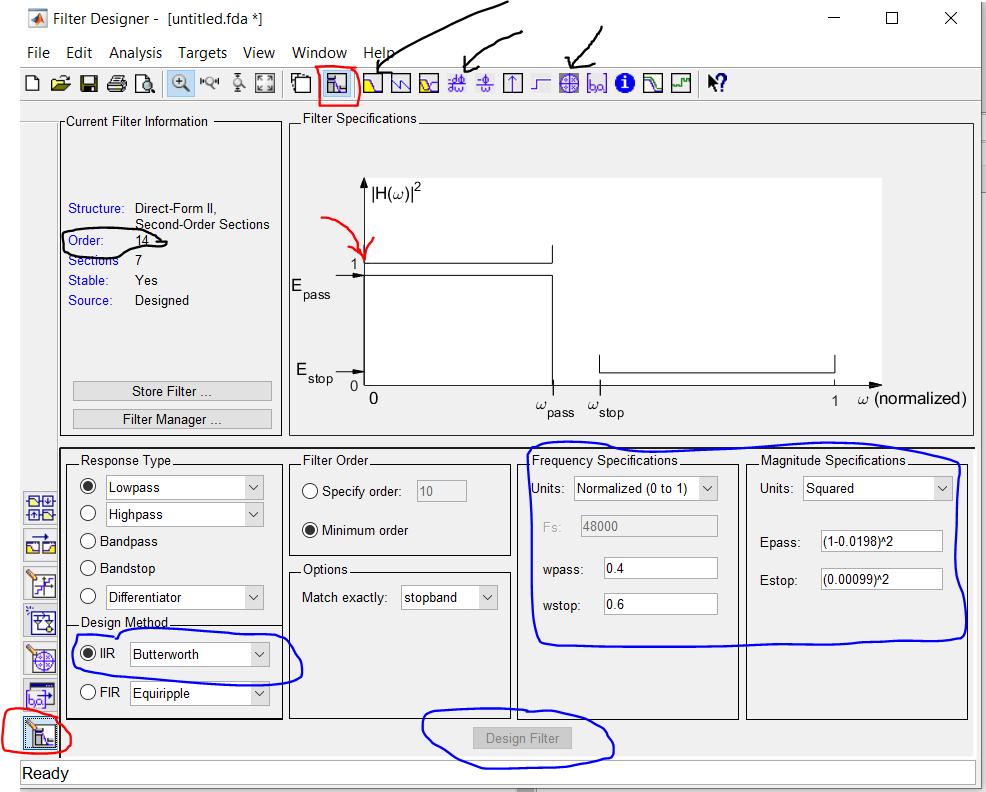

                                                      Fig 1: IIR Butterworth Filter Design

- **Rescaling parameters:**  Now, if you look at the magnitude response (by clicking on the tab besides the red annotated box), you can see that the above filter has gain of $0.9914$at $0.4\pi
$and $0.00099$at $0.6\pi$. Note that the design already satisfies the required specification. However, in some cases, if the required specification is not met, you need to rescale back the impulse response or numerator coefficients by $1+{\delta_{p_1}}$ to match the desired response. 

- **Filter Analysis: **Now, we will look at magnitude response, group delay and pole-zero plots and order of the filter (black annotations in Fig. 1). 

              - Filter order is 14. 

              - Both passband and stopbands have monotonic behaviour. 

              - There are 14 zeros at $-1$. Since all the poles are inside the unit circle, the filter is stable. 

              - The group delay is highest in the transition band and below 15 in the passband. 

          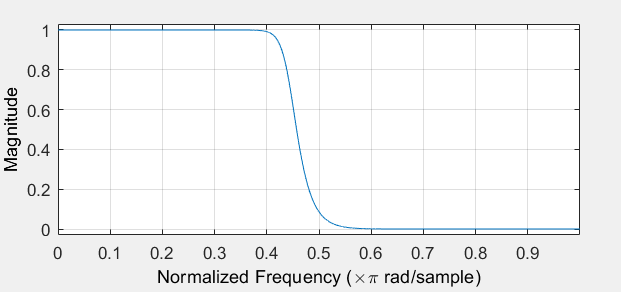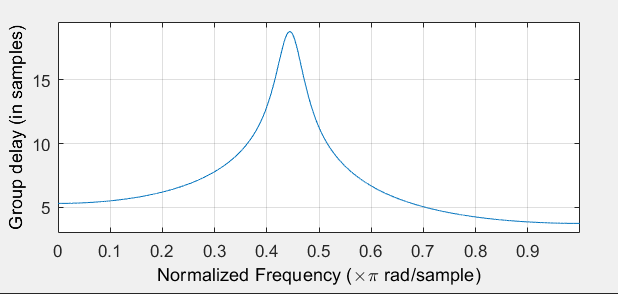

                               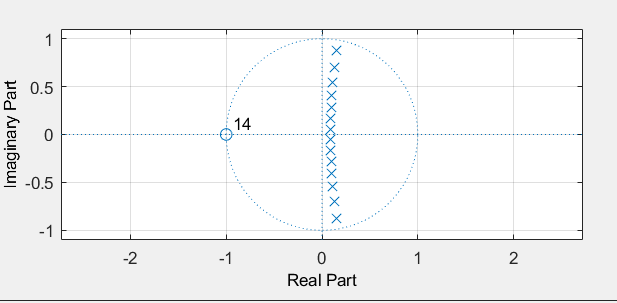

### IIR Chebyshev Type 1 

% Enter the filter coefficients

Answer the following:

- Order of the filter

*            ANSWER*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

### IIR Chebyshev Type 2 

% Enter the filter coefficients

Answer the following:

- Order of the filter

*            ANSWER*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

### FIR Window - Kaiser 

% Enter the filter coefficients

Answer the following:

- Order of the filter

*            ANSWER*

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER*

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

### Common Questions :

After all the filter designs are completed, answer the below questions. 

- Among IIR filters, which filter gives the lowest order? What is the practical use of having a lowest order filter (think in terms of number of multiplications in the implementation)? 

            *ANSWER*

- Among the FIR filters, which method gives the lowest order? Compare this with orders of IIR filters. 

            *ANSWER*

- For a given filter specification, if you want the filter order to be as small as possible, which implemetation would you choose, FIR or IIR? Which one among them? 

            *ANSWER*

- FIR filters are always stable, but IIR filters may or may not be stable (True or False)? 

            *ANSWER*

- Comment on the group delays of FIR and IIR filters. Which design would you prefer (FIR or IIR) if the filter order is not important but a constant group delay is required? 

            *ANSWER*

### Thank you!